# Generating Features from the Flights Dataset

## Introduction

This reading contains examples of how to use existing variables to generates new features in the Flights dataset. The examples will cover three general approaches for feature generation:

- Discretization

- Summarizing Groups

- Transforming Variables

## Import the Flights Dataset

Import the files flightsFeb.csv and airports.csv.

flights = importFlightsData("flightsFeb.csv"); % Import one month of data
airports = readtable("airports.csv"); % Import the airports data

## Discretization

One technique for generating new features is discretizing existing variables. Discretization groups numeric data into bins based on their values. Here are a few examples:

### Discretize datetimes by day of the month

Each row in the data represents a single flight. However, sometimes we are more interested in aggregate data, like how many flights occur on each day of the month. Are some days more popular than others?

To find out, discretize the data into groups based on day of the month they occurred on. Use the [`day`](https://www.mathworks.com/help/matlab/ref/datetime.day.html) and [`histogram`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) functions for this.

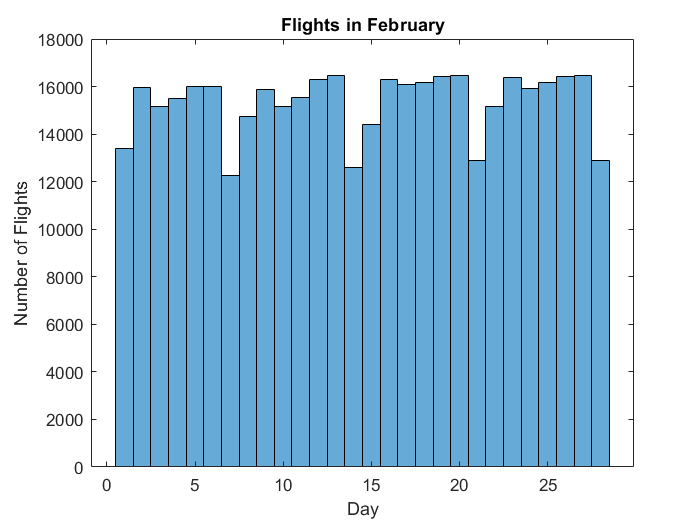

% Create a new feature by discretizing by day of month
flights.DAY_OF_MONTH = day(flights.SCHEDULED_DEPARTURE_TIME);

% Plot a histogram of the results
histogram(flights.DAY_OF_MONTH);
title("Flights in February")
xlabel("Day")
ylabel("Number of Flights")

For February, the result shows a clear 7-day cycle. Can your determine the days of the week from the histogram?

### Discretize numbers into categories

Perhaps you needed to know how many of those flights were delayed? The data contains information on how many minutes delayed each flight was. The [`discretize`](https://www.mathworks.com/help/matlab/ref/double.discretize.html) function can split that data into two groups - On Time and Delayed - using numeric ranges you provide. This classification is a new feature of the data.

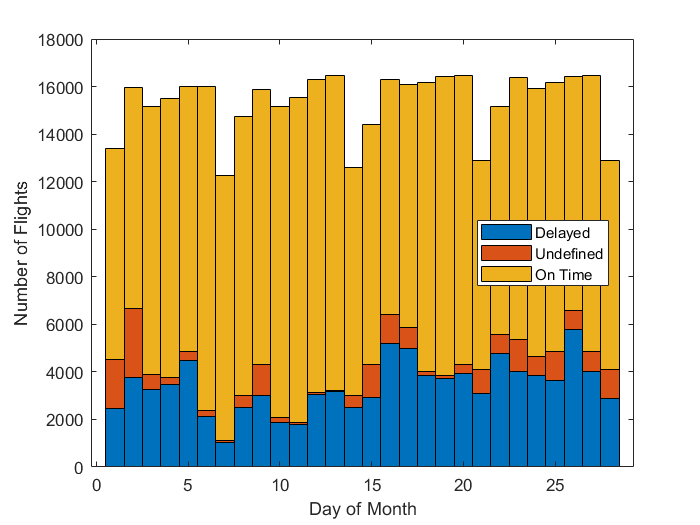

% Create a new feature, with flights arriving <= 15 minutes delayed categorized as "On Time"
% Flights that are > 15 minutes delayed are categorized as "Delayed"
flights.DELAYED = discretize(flights.ARRIVAL_DELAY,[-inf,15,inf],"categorical",["On Time", "Delayed"]);

% Count the number of Delayed and On Time flights for each day of the month
delayedSummary = groupsummary(flights,["DAY_OF_MONTH","DELAYED"]);
% Extract the index for each category for each day of the month
UD = ismissing(delayedSummary.DELAYED); % undefined
D = delayedSummary.DELAYED == "Delayed";
OT = delayedSummary.DELAYED == "On Time";

% Plot the resulting counts in a stacked bar plot. 
% Compare the results to the number of flights per day plotting above.
bar(unique(delayedSummary.DAY_OF_MONTH),...
    [delayedSummary.GroupCount(D) ...
    delayedSummary.GroupCount(UD) ...
    delayedSummary.GroupCount(OT)],1,"stacked")
xlabel("Day of Month")
ylabel("Number of Flights")
legend(["Delayed","Undefined","On Time"],"Location","best")

It looks like there were several days with a higher than usual number of flights that did not arrive on time (e.g. February 2nd, 16th, 17th, and 26th). If you want to practice further, explore the Undefined flights. This includes flights that were canceled as well as flights that do not have a value for arrival delay. Use the variable `CANCELLATION_CODE` to discretize the cancelled flights. The letter codes correspond to:

- A = Airline Cancellation

- B = Weather Cancellation

- C = National Air System Cancellation

- D = Security Cancellation

## Summarizing Data by Groups

Another technique for engineering features is summarizing data by groups.

There are lots of ways you can group flights data - by origin, destination, route, flight number, tail number, airline, etc. This example will explore the average time it takes to taxi out from the gate. To begin, summarize the taxi out times by airport. This displays typical values for each airport along with the corresponding number of scheduled flights, an indication of airport size.

temp = groupsummary(flights,"ORIGIN","median","TAXI_OUT");
airportTaxiOutSummary = sortrows(temp,"median_TAXI_OUT","descend")

airportTaxiOutSummary = 315×3 table
    ORIGIN    GroupCount    median_TAXI_OUT
    ______    __________    _______________

     BGM           38            30.5      
     BGR           21              26      
     LGA         8945              25      
     DVL           44              23      
     IMT           52              23      
     BOS         8380              22      
     CIU           52              22      
     JFK         7740              22      
     PLN           49              22      
     ROC          559              22      
     SBN          394              22      
     SYR          423              22      
     INL           48            21.5      
     CMX           56              21      
     ISN          235              21      
     MOT          133              21      


Add this information as a new variable to the flights table using the [join](https://www.mathworks.com/help/matlab/ref/matlab.unittest.diagnostics.diagnostic.join.html) function. Then create a new feature by taking the difference between the actual taxi out time and average taxi out time at that airport.

% Join the tables
flightsJoined = join(flights,airportTaxiOutSummary,"Keys","ORIGIN","RightVariables","median_TAXI_OUT");

% Create a new feature of the difference between the taxi out time and the median time for its origin airport
flightsJoined.TAXI_OUT_DIFF = flightsJoined.TAXI_OUT - flightsJoined.median_TAXI_OUT;

A new question to answer might be this: is this difference constant across all flights departing from the same airport or are there certain flights that tend to have longer taxi out times? Flights are identified by flight numbers, which generally identify a unique scheduled route. For example, flight number 1647 from LaGuardia Airport is always the daily 8:00am flight to Atlanta Airport.

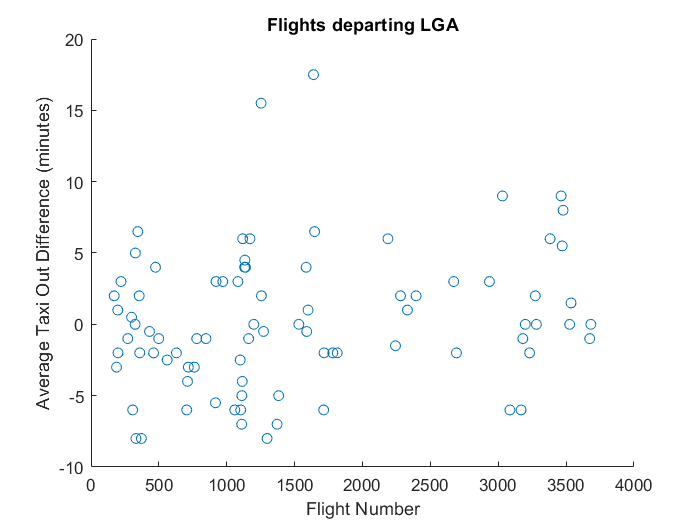

% Start by selecting an airport
originAirport = 'LGA';

% Take only flights originating from the chosen airport.
flightsAirport = flightsJoined(flightsJoined.ORIGIN == originAirport,:);

% Group flights from the selected airport by flight number and compute the median taxi out time for each group
taxiOutSummary = groupsummary(flightsAirport,"FLIGHT_NUMBER","median","TAXI_OUT_DIFF");

% Take only flights that happen at least once a day
taxiOutSummary = taxiOutSummary(taxiOutSummary.GroupCount >= max(flights.DAY_OF_MONTH),:);

% Plot the results
scatter(taxiOutSummary.FLIGHT_NUMBER,taxiOutSummary.median_TAXI_OUT_DIFF)
title("Flights departing " + originAirport)
xlabel("Flight Number")
ylabel("Average Taxi Out Difference (minutes)")

There are two flights numbers with median taxi out times greater than 15 minutes (for LGA in February). For additional practice, see if you can identify what the destinations of these two routes are.

## Transforming Variables

The final technique covered in this reading is data transformation. In its simplest form, transforming applies an equation to existing data to create a new feature. This section will walk through an example of this using the flights dataset.

Assume you are trying to predict the flight duration for a new route between two airports and have no prior information available for this route. You do have lots of information about other flights. Let's look at how you might create a model to predict the duration of the new route. The purpose of this example is to demonstrate feature engineering. Specifics about how the models work are outside the scope of this reading.

Duration will depend most on the distance between the origin and destination. The code below creates a model from the flights dataset that uses distance to estimates the scheduled elapsed time between any two airports.

% Linear model for predicting elapsed time from distance.
basicModel = fitlm(flights(:,["SCHEDULED_ELAPSED_TIME","DISTANCE"]),...
    'PredictorVar','DISTANCE','ResponseVar','SCHEDULED_ELAPSED_TIME');

% R-squared value
rSquaredBasic = basicModel.Rsquared.Ordinary

rSquaredBasic = 0.9553

R-squared is a measure of goodness-of-fit. It measures much of the variability in the scheduled elapsed time is explained by the distance. Ninety-six percent may seem pretty good, but let's see if we can't improve it. Let's look at all the flights arriving and departing from Boston (BOS).

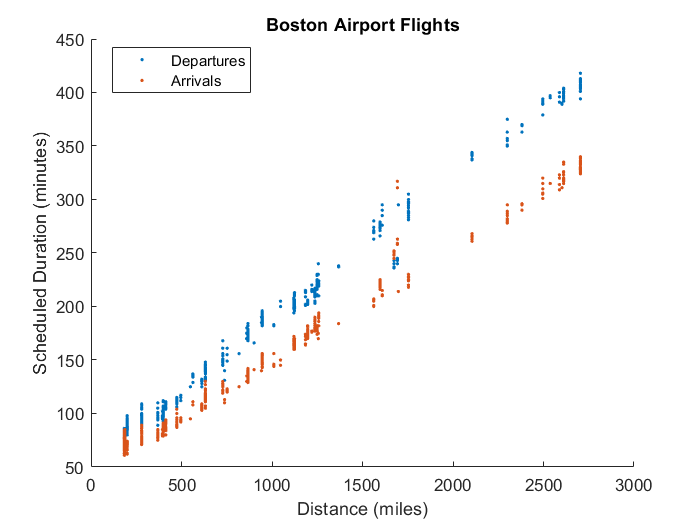

Notice how arriving flights take significantly less time than departing flights, even if they cover the same distance. Why is this?

Boston is on the east coast, so most departures fly West while most arrivals fly East. The direction of a flight appears to have significant impact on its duration. This is because of the atmospheric jet stream, a fast moving West-to-East air current that can reach speeds of 200 km/h. Therefore, flights going West must fly against the jet stream, making them take longer than flights on the same route heading East.

How can the model account for the effect of the jet stream? You can add a new feature to indicate direction and include that in the model.

To do this, you'll need the geographic information for each flight's origin and destination. This can be added from the airports data.

% Make AIRPORT a categorical so that it matches the key variable in the flights table
airports.AIRPORT = categorical(airports.AIRPORT);

% Join tables to capture the origin airport geographic data
flightsTemp = join(flights,airports,"LeftKeys","ORIGIN","RightKeys","AIRPORT",...
    "RightVariables",["LATITUDE","LONGITUDE"]);

% Join tables again to capture the destination airport geographic data
flights = join(flightsTemp,airports,"LeftKeys","DESTINATION","RightKeys","AIRPORT",...
    "RightVariables",["LATITUDE","LONGITUDE"]);

% Rename the new variables for easier referencing
flights.Properties.VariableNames(end-3:end) = {'LATITUDE_ORIGIN', 'LONGITUDE_ORIGIN', 'LATITUDE_DESTINATION', 'LONGITUDE_DESTINATION'};

Next, you need a quantitative method to capture how much a flight is going East vs West. There are many ways to do this, but the one used here is to calculate the azimuthal angle of the flight path. This is the angle at the origin airport between the north pole and the destination airport. For example, a flight heading:

- North has an azimuthal angle of 0 degrees.

- East has an azimuthal angle of 90 degrees.

- West has an azimuthal angle of -90 (or 270) degrees.

You can use the `azimuth` function to calculate this angle from the latitude and longitude data for the origin and destination airports.

flights.AZIMUTH = azimuth(flights.LATITUDE_ORIGIN,flights.LONGITUDE_ORIGIN,...
    flights.LATITUDE_DESTINATION,flights.LONGITUDE_DESTINATION);

Finally, the jet stream effect means that you only need to quantify how much a flight is heading East vs West, not North vs South. You can capture this direction in a single number by taking the sine of the azimuthal angle. For example, a flight heading:

- North/South has an azimuthal sine of 0.

- East has an azimuthal sine of 1.

- West has an azimuthal sine of -1.

% Take the sine of the Azimuthal angle. Since azimuth is in degrees, use the sind function.
flights.SIN_AZIMUTH = sind(flights.AZIMUTH);

Below is the updated model that predicts a flight's scheduled elapsed time using both distance and the newly generated feature SIN_AZIMUTH.

% Basic linear model predicting a flight's elapsed time from its distance and direction.
advancedModel = fitlm(flights(:,["SCHEDULED_ELAPSED_TIME","DISTANCE","SIN_AZIMUTH"]),...
    'interactions','ResponseVar','SCHEDULED_ELAPSED_TIME');

% R-squared value
rSquaredAdvanced = advancedModel.Rsquared.Ordinary

rSquaredAdvanced = 0.9849

As you can see, including distance and a measure of direction in the model explains 98.5% of variability in the scheduled elapsed time.

What other inputs do you think could improve this model? How could you create those features using the techniques you've learned and information you have?